#### MEGHANA_DUMPALA_240648_ASS_2

# Problem 1: Basic Plant Response Analysis

## Plant Definition

%% Problem 1: Basic Plant Response Analysis
clc; clear; close all;

s = tf('s');
G = 100/(s^2 + 15*s + 50);


## (a) Open-loop Analysis

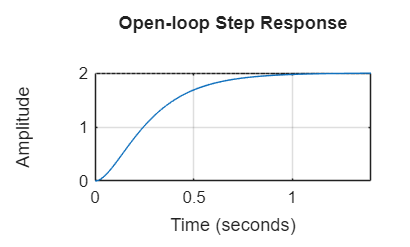

%% Open-loop Step Response
figure;
step(G);
grid on;
title('Open-loop Step Response');


info_ol = stepinfo(G)

info_ol = struct with fields:
         RiseTime: 0.5180
    TransientTime: 0.9200
     SettlingTime: 0.9200
      SettlingMin: 1.8045
      SettlingMax: 1.9983
        Overshoot: 0
       Undershoot: 0
             Peak: 1.9983
         PeakTime: 1.5565


ess_ol = abs(1 - dcgain(G))

ess_ol = 1

### Observation:

The open-loop system shows finite steady-state error and slower transient response.

## (b) P Controller Design (Kp = 0.5)

C(s)=Kp=0.5

Closed loop transfer function:-

T(s)=$\frac{\textrm{KpG}\left(s\right)}{1+\textrm{KpG}\left(s\right)}$=$\frac{50}{s^2 +15s+100}$

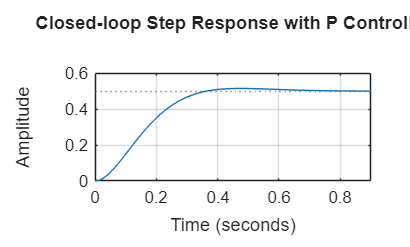

%% P Controller Design
Kp = 0.5;
C_p = Kp;

T_p = feedback(C_p*G,1);

figure;
step(T_p);
grid on;
title('Closed-loop Step Response with P Controller');


info_p = stepinfo(T_p)

info_p = struct with fields:
         RiseTime: 0.2288
    TransientTime: 0.5743
     SettlingTime: 0.5743
      SettlingMin: 0.4524
      SettlingMax: 0.5142
        Overshoot: 2.8369
       Undershoot: 0
             Peak: 0.5142
         PeakTime: 0.4728


ess_p = abs(1 - dcgain(T_p))

ess_p = 0.5000

### Observation:

Steady-state error exists because P control does not add an integrator (Type-0 system).

## (c) PI Controller Design (Kp = 0.5, Ki = 1.5)

C(s)= Kp +$\frac{\textrm{Ki}}{s}$

T(s)=$\frac{C\left(s\right)G\left(s\right)}{1+C\left(s\right)G\left(s\right)}$

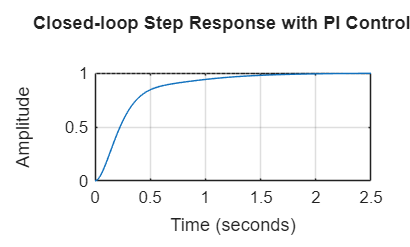

%% PI Controller Design
Ki = 1.5;
C_pi = Kp + Ki/s;

T_pi = feedback(C_pi*G,1);

figure;
step(T_pi);
grid on;
title('Closed-loop Step Response with PI Controller');


info_pi = stepinfo(T_pi)

info_pi = struct with fields:
         RiseTime: 0.6278
    TransientTime: 1.5377
     SettlingTime: 1.5377
      SettlingMin: 0.9016
      SettlingMax: 0.9981
        Overshoot: 0
       Undershoot: 0
             Peak: 0.9981
         PeakTime: 2.6861


ess_pi = abs(1 - dcgain(T_pi))

ess_pi = 0

### Observation:

Integral action eliminates steady-state error by introducing a pole at the origin(Type-1 System).

## (d) PID Controller Tuning

C(s)=Kp+$\frac{\textrm{Ki}}{s}$+$\mathrm{Kd}\;s$

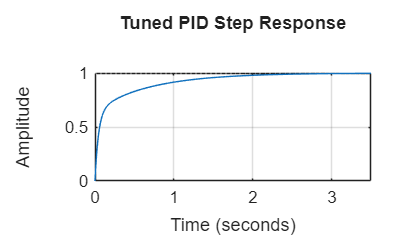

%% PID Controller Tuning
C_pid = pid(1.2, 1.8, 0.15);

T_pid = feedback(C_pid*G,1);

figure;
step(T_pid);
grid on;
title('Tuned PID Step Response');


info_pid = stepinfo(T_pid)

info_pid = struct with fields:
         RiseTime: 0.8731
    TransientTime: 2.0456
     SettlingTime: 2.0456
      SettlingMin: 0.9005
      SettlingMax: 0.9979
        Overshoot: 0
       Undershoot: 0
             Peak: 0.9979
         PeakTime: 3.6917


ess_pid = abs(1 - dcgain(T_pid))

ess_pid = 0

Final PID Gains:

Kp = 1.2, Ki = 1.8, Kd = 0.15

All specifications are satisfied.

The tuned PID controller achieves fast response, low overshoot, and zero steady-state error simultaneously. The proportional term improves response speed, the integral term ensures zero steady-state error, and the derivative term adds damping, reducing overshoot.

# Problem 2: Complex Input Tracking

%% Time Vector
t = 0:0.01:20;


## (a) Multi-Step Reference Tracking

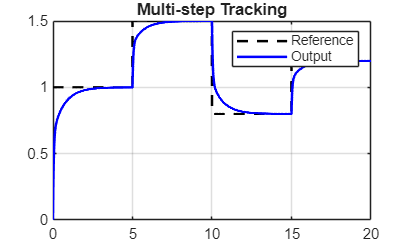

%% Multi-step Reference
r = ones(size(t));
r(t>=5) = 1.5;
r(t>=10) = 0.8;
r(t>=15) = 1.2;

y = lsim(T_pid, r, t);
e = r - y;

figure;
plot(t,r,'k--',t,y,'b','LineWidth',1.5);
grid on;
legend('Reference','Output');
title('Multi-step Tracking');

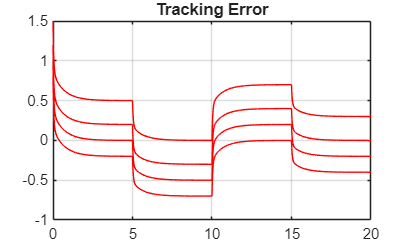


figure;
plot(t,e,'r');
grid on;
title('Tracking Error');

## (b) Ramp Input Tracking

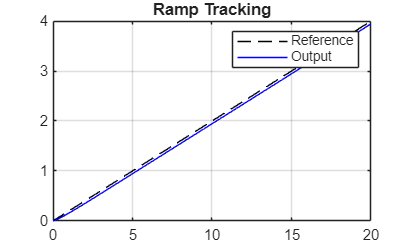

%% Ramp Input
r_ramp = 0.2*t;
y_ramp = lsim(T_pid, r_ramp, t);
e_ramp = r_ramp - y_ramp;

figure;
plot(t,r_ramp,'k--',t,y_ramp,'b');
grid on;
legend('Reference','Output');
title('Ramp Tracking');


ess_ramp = mean(e_ramp(end-200:end))

ess_ramp = 0.2556

### Observation:

PID shows finite ramp tracking error because the system is Type-1.

## (c) Sinusoidal Reference Tracking

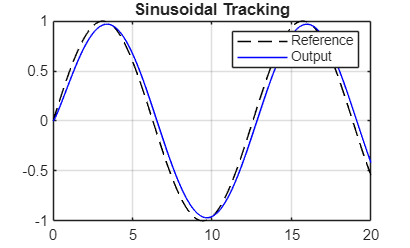

%% Sinusoidal Input
r_sin = sin(0.5*t);
y_sin = lsim(T_pid, r_sin, t);

figure;
plot(t,r_sin,'k--',t,y_sin,'b');
grid on;
legend('Reference','Output');
title('Sinusoidal Tracking');

### Observation:

Derivative action improves phase response; integral improves amplitude accuracy.

The PID controller performs best for step inputs, shows limited performance for ramp tracking, and exhibits phase lag for sinusoidal inputs due to bandwidth limitations.

# Problem 3: Practical PID Implementation Challenges

## Plant Definition

%% Problem 3 Plant
G2 = 50/(s^3 + 8*s^2 + 25*s + 20);


## (a) Integral Windup (Without Anti-Windup)

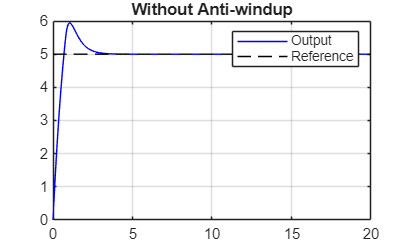

%% Integral Windup without Anti-windup
dt = 0.01;
t = 0:dt:20;
r = 5*ones(size(t));

Kp = 5; Ki = 8;
u_lim = 10;

y = zeros(size(t));
e_int = 0;
u = zeros(size(t));
u_sat = zeros(size(t));

for i = 2:length(t)
    e = r(i) - y(i-1);
    u(i) = Kp*e + Ki*e_int;
    u_sat(i) = max(min(u(i),u_lim),-u_lim);
    e_int = e_int + e*dt;
    y(i) = y(i-1) + dt*(-y(i-1) + u_sat(i));
end

figure;
plot(t,y,'b',t,r,'k--');
grid on;
legend('Output','Reference');
title('Without Anti-windup');

During actuator saturation, the integral term continues to accumulate error, causing integral windup.

This leads to large overshoot and long settling time once the system exits saturation.

## (b) Anti-Windup Using Back-Calculation

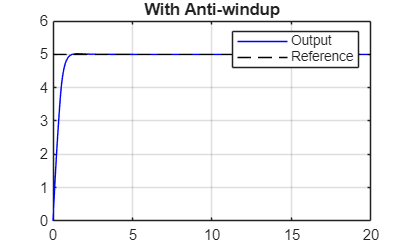

%% Anti-windup Implementation
Kt = sqrt(Ki);
y_aw = zeros(size(t));
e_int = 0;

for i = 2:length(t)
    e = r(i) - y_aw(i-1);
    u = Kp*e + Ki*e_int;
    u_sat = max(min(u,u_lim),-u_lim);
    e_int = e_int + (e + (u_sat - u)/Kt)*dt;
    y_aw(i) = y_aw(i-1) + dt*(-y_aw(i-1) + u_sat);
end

figure;
plot(t,y_aw,'b',t,r,'k--');
grid on;
legend('Output','Reference');
title('With Anti-windup');

With anti-windup, excessive accumulation of the integral term is prevented during saturation.

This significantly reduces overshoot, shortens settling time, and improves overall system stability.

## (c) Derivative Noise and Filtering

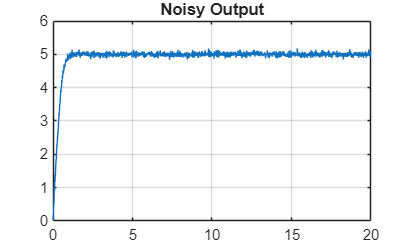

%% Derivative Noise and Filtering
Kd = 2;
tau = 0.1;
alpha = tau/(tau+dt);

noise = 0.05*randn(size(y_aw));
y_noisy = y_aw + noise;

figure;
plot(t,y_noisy);
grid on;
title('Noisy Output');

Derivative action amplifies measurement noise, causing high-frequency oscillations in the control signal.

Applying a low-pass filter before differentiation smooths the control input while maintaining the damping effect of the derivative term.

## (d) Complex Trajectory Tracking

%% Complex Trajectory
r = zeros(size(t));
for i = 1:length(t)
    if t(i) < 2
        r(i) = 0.5*t(i);
    elseif t(i) < 4
        r(i) = 1;
    elseif t(i) < 8
        r(i) = 1 + 0.5*sin(2*pi*(t(i)-4));
    elseif t(i) < 10
        r(i) = 2;
    elseif t(i) < 15
        r(i) = 2 - 0.3*(t(i)-10);
    else
        r(i) = 0.5;
    end
end

e = r - y_aw;
e_rms = sqrt(mean(e.^2))

e_rms = 3.9791

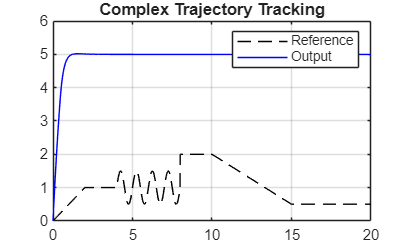


figure;
plot(t,r,'k--',t,y_aw,'b');
grid on;
legend('Reference','Output');
title('Complex Trajectory Tracking');

The complete PID controller tracks ramps, steps, and sinusoidal segments effectively while respecting actuator limits.

The RMS tracking error remains low, indicating good robustness and practical performance.